# Post-activation Depression Analysis - Individual analysis

Developed by Pedro Valadão (pvaladao@tuta.io). Last Modified: 04/03/2021.

This script calculates the peak to peak amplitude of the M-wave and H-reflex for the soleus muscle. Then it calculates PAD as the ratio between normalized values of H-reflex in fast and slow conditions.

Trial description: initial stimulation to find the intensity to attain H75, then 16 stimuli at 0.1Hz and 16 at 1Hz. So in practice there is always more than 16 slow stimuli, the script analyzes all and exclude the outliers. There may be more stimuli depending on what happened during the testing session.

#### *Input: Test session, group (CP:51xx or TD:52xx), file name, datapath and Hmax. *

## Import data

clear,clc
dataPath = 'C:\Doutorado\Matlab\Paper II\Electrical Stimulation\PAD\smr_PAD\';
fileName = '5215_pre1_PAD.smr';
data =ImportSMR([dataPath fileName]);
Subject = string(fileName(1:4));
Test = "Pre_1"; 
Group = "TD";
load recruitment_all.mat
H_max = H_all.Hmax(H_all.Subject == Subject)

H_max = 3.8553

## Define Variables

Check if electro stimulation event channel (ES) is correct: it may be 11, 10 (5101), 9 or 6 (02/03/04/06/05/07/8/9/10/12/5201, adjust on line 13. Keyboard channel has to be adjusted on line 15: 15 (5101), 7 (5102/03), 8 (04/05, 5106/07/8/5201/03), 11 (09/10/12/5204), 

sol_raw = double(data(3).imp.adc)*data(3).hdr.adc.Scale; % converted to double and scaled
sol_freq = 1/(data(3).hdr.adc.SampleInterval(1)*data(3).hdr.adc.SampleInterval(2)); % sampling rate for EMG
time = seconds([1:1:length(data(3).imp.adc)]'/sol_freq); % time vector in seconds
stim_s = ((double(data(6).imp.tim))*data(6).hdr.tim.Units*data(6).hdr.tim.Scale); % time in s when the ES happened
stim = (stim_s * sol_freq); % converts event from time to sample 
%key = seconds(double(data(8).imp.tim)*data(8).hdr.tim.Units*data(8).hdr.tim.Scale);
key = [66 235], key = seconds(key)

key =     66   235


key = 1×2 duration array
    66 sec   235 sec


## Pre processing

Bandpass Sol EMG 20-195 Hz. Calculate background noise level in a 3 s window before the first stim.

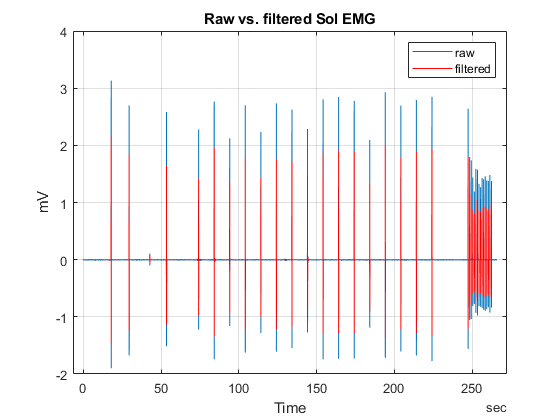

fcutlow=20;   %low cut frequency in Hz
fcuthigh=195;   %high cut frequency in Hz
[b0,a0]=butter(4,[fcutlow,fcuthigh]/(sol_freq/2),'bandpass'); %4th order butterworth bandpass 20-195Hz 
sol = filtfilt(b0,a0,sol_raw); % filtered sol EMG
plot(time,sol_raw), title('Raw vs. filtered Sol EMG'),xlabel('Time'), ylabel('mV'), grid on,
hold on,
plot(time,sol,'r'),legend({'raw','filtered'})
hold off

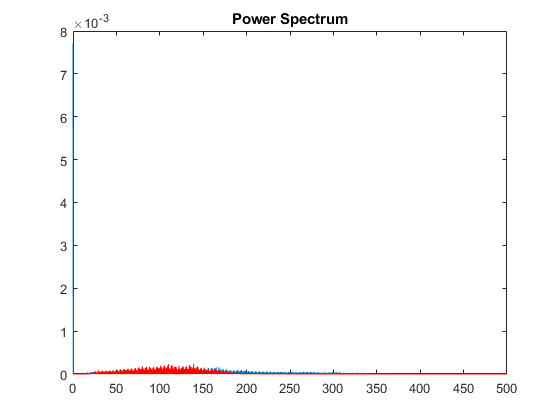

[Sol_Raw_Spectrum,Sol_Raw_Frequencies] = periodogram(sol_raw,[],[],sol_freq); %sol raw pediodogram
[Sol_Spectrum,Sol_Frequencies] = periodogram(sol,[],[],sol_freq); %sol filtered pediodogram
plot(Sol_Raw_Frequencies,Sol_Raw_Spectrum),xlim([0 500]),ylim('auto'),title('Power Spectrum'), 
hold on,
plot(Sol_Frequencies,Sol_Spectrum,'r'),xlim([0 500]),ylim('auto'),
hold off, 

sample_3s_before = round(stim(2)- (3*sol_freq)); % sample 3 s before second stim (there may not be 3 s before the first)
sample_before = round(stim(2)- (0.010*sol_freq)); % sample 10 ms before second stim
pre_3_raw = sol_raw(sample_3s_before:sample_before) ; % 3s of data before first stim in raw sol
pre_3_filt = sol(sample_3s_before:sample_before); % 3s of data before first stim in filtered sol
p2p_raw = peak2peak(pre_3_raw),  % peak to peak amplitude of raw signal

p2p_raw = 0.0136

p2p_filt = peak2peak(pre_3_filt), % p2p amplitude of filtered signal

p2p_filt = 0.0196

noise_raw = rms(pre_3_raw) % rms of the raw signal in a 3s window

noise_raw = 0.0056

noise_filt = rms(pre_3_filt) % rms of the filtered signal in a 3s window

noise_filt = 0.0011

%if p2p_filt > 0.045 || noise_filt > 0.05
 %   error('high background noise level!')
%end

## Data Analysis

Eliminate all ES that happened before the first keyboard mark. This is necessary because the first few stimuli are used to adjust the stimulation intensity to achieve 75%Hmax. After the adjustment the researcher presses the buttom to start the automatic 16 stimuli at 0.1 Hz. A second keyboard marker shows the beggining of the 1 Hz stimuli.   

r = 1;
for Trial = seconds(stim_s')
    if Trial < key(1)
        stim_s(r) = 0;
        r = r + 1; 
    else
    end
end
logi = logical(stim_s ~= 0);
stim = stim(logi);% remove all events that happened before the first keyboard marker
stim_s = stim_s(logi);

Calculte peak to peak amplitude in the regions of interrest. Create result array (M-wave, Hreflex, H/M, H/Hmax, dt) and event array (electrical stimulus, m-onset, m-offset, h-offset). dt = time between current stimulus and the previous one (used to determined condition).

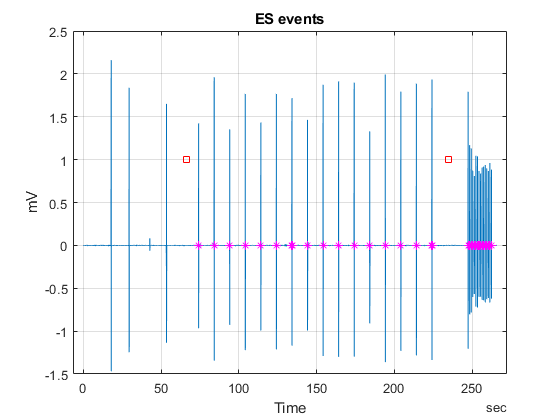

results = zeros(length(stim_s),5); %pre-allocation for M-wave,H-reflex,H/M, dt and Condition (fast or slow) results. 
event_list = zeros(length(stim_s),4); %pre-allocation for time in seconds of ES, M onset, M offset and H onset. 
m_onset = (0.005*sol_freq);  %5ms in samples
m_offset = (0.022*sol_freq); %22ms in samples 
h_offset = (0.05*sol_freq);  %50 ms in samples
row = 1;
for ES = stim' 
    M_ROI = [ES + m_onset:ES+ m_offset];% region of interest for M-wave 5-22ms after ES
    M_wave = peak2peak(sol(floor(M_ROI))); % p2p m-wave
    H_ROI = [ES + m_offset:ES+ h_offset]; %region of interest for H-reflex 22-50ms after ES
    H_reflex = peak2peak(sol(floor(H_ROI))); %p2p H-reflex
    results (row,1) = M_wave;
    results (row,2) = H_reflex;
    results (row,3) = H_reflex/M_wave;
    results (row,4) = H_reflex/H_max;
    try 
         dt = stim_s(row)- stim_s(row-1); % avoid error when row = 1
    catch ME
        dt = 10;   %set dt of the first stim to 10 (to be classified as slow condition)
    end   
    results (row,5) = dt; %time in seconds between 2 stimuli 
      if dt < 1.1 
          results (row,6) = 2; %stim = fast condition
      elseif  dt > 9.5
          results (row,6) = 1; %stim = slow condition
      end      
    event_list (row,1) = ES;
    event_list (row,2) = ES + m_onset; 
    event_list (row,3) = ES + m_offset;
    event_list (row,4) = ES + h_offset;
    row = row + 1;   
end 
event_list = seconds(event_list/sol_freq); %converts samples to seconds
ys = zeros (length(event_list),1); %list of zeros to plot data
figure, plot(time,sol), title('ES events'),xlabel('Time'), ylabel('mV'), grid on,
hold on, %create graph showing the events of interrest:
plot(event_list(:,1),ys,'r*'), plot(event_list(:,2),ys,'m*'),
plot(event_list(:,3),ys,'m*'),plot(event_list(:,4),ys,'m*'),
plot(key, 1, 'sr')
hold off

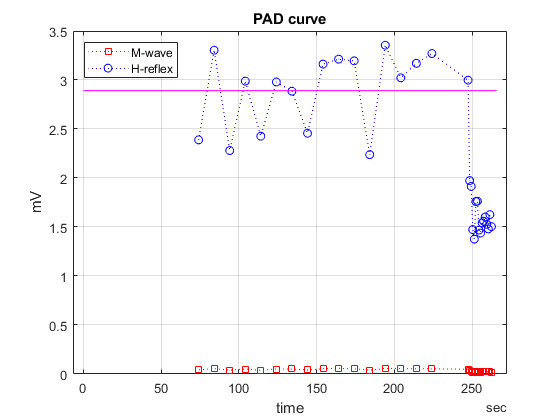

target_h(1:(length(time))) = H_max*0.75; %target h amplitude for the slow condition
figure, plot(event_list(:,1),results(:,1),'rs:')
hold on, 
plot(event_list(:,1),results(:,2),'bo:'),plot(time,target_h,'m-')
legend({'M-wave','H-reflex'},'location','northwest'),title('PAD curve'),xlabel('time'),ylabel('mV'), grid on
hold off

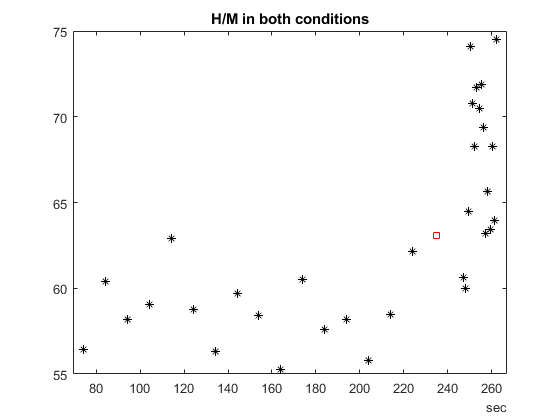

plot(event_list(:,1), results(:,3), 'k*'), 
hold on, 
plot(key(2), (mean(results(:,3))), 'sr'), title('H/M in both conditions'), %square marks the transition between conditions

### Remove outliers from raw data

Outliers were usually caused by small muscle contraction/movements during the test, especially for the CP participants in the slow condition. The median absolute deviation  is calculated as: MAD = 1.4826*median(abs(h_slow-median( h_slow))). Then MAD is multiplied by the threshold factor (currently using 2.5 which is more constrained than the default value of 3. Processed data table (condition,  M-wave,  H-reflex, H/M, H/H_max). Because the amplitude of the H-reflex is dependent on the effective stimulation intensity, the normalized H/M was used to check for outliers. 

    M_wave = results (:,1); 
    H_reflex = results (:,2); 
    H_M = results (:,3);
    H_Hmax = results (:,4); 
    Condition = categorical(results (:,6),[1 2],{'Slow','Fast'}); %categorical variable for condition
    raw_data = table(M_wave,H_reflex,H_M,H_Hmax,Condition); %raw results
    raw_data = sortrows(raw_data,'Condition'); % slow first then fast
    h_slow = raw_data.H_M(raw_data.Condition == 'Slow', :); 
    h_fast = raw_data.H_M(raw_data.Condition == 'Fast', :);

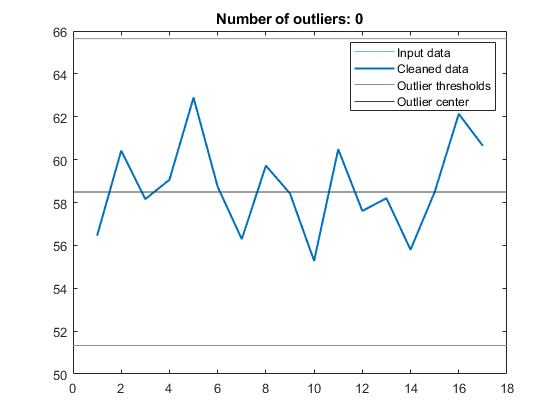

% Remove outliers
[cleanedSlow,outlierSlow] = rmoutliers(h_slow,'ThresholdFactor',2.5);

% Visualize results
clf
plot(h_slow,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(find(~outlierSlow),cleanedSlow,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierSlow),h_slow(outlierSlow),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierSlow))])

% Compute thresholds and center
[~,thresholdLow,thresholdHigh,center] = isoutlier(h_slow,'ThresholdFactor',2.5);

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

% Plot outlier center
plot(xlim,[center,center],'Color',[64 64 64]/255,'DisplayName','Outlier center')

hold off
legend

clear thresholdLow thresholdHigh center

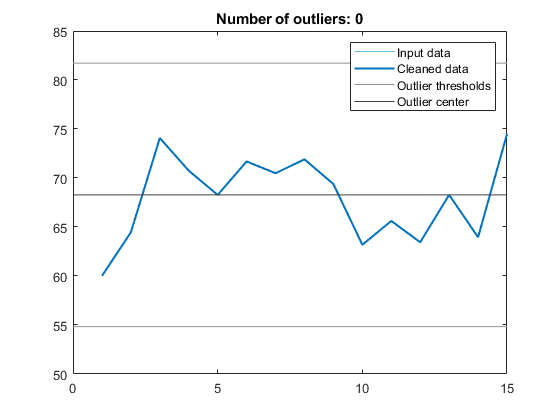

% Remove outliers
[cleanedFast,outlierFast] = rmoutliers(h_fast,'ThresholdFactor',2.5);

% Visualize results
clf
plot(h_fast,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(find(~outlierFast),cleanedFast,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierFast),h_fast(outlierFast),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierFast))])

% Compute thresholds and center
[~,thresholdLow2,thresholdHigh2,center] = isoutlier(h_fast,'ThresholdFactor',2.5);

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow2*[1 1] NaN thresholdHigh2*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

% Plot outlier center
plot(xlim,[center,center],'Color',[64 64 64]/255,'DisplayName','Outlier center')

hold off
legend

clear thresholdLow2 thresholdHigh2 center
outlier_all(1:length(outlierSlow)) = outlierSlow; %logical vector for outliers in the slow condition
outlier_all(end+1:end+length(outlierFast)) = outlierFast; %logical vector with outliers of both conditions
raw_data.outlier_all = outlier_all'; %outlier logical vector merged into raw_data table
processed_data = raw_data(raw_data.outlier_all == false,:); %data without outliers
processed_data = movevars(processed_data, "Condition","Before","M_wave"); %change col order
processed_data = removevars(processed_data,"outlier_all"); %remove outlier logical vector

## Descriptive Statistics & PAD calculation

Descriptive statistics for the variables + subject/group/test information. PAD is calculated as the ratio between (Fast/Slow) of the peak to peak mean values of the absolute H-reflex and the H/M (H-reflex normalized by preceeding M-wave).  

descriptive = groupsummary(processed_data,"Condition",{'mean','std','median'},...
    {'M_wave','H_reflex','H_M','H_Hmax'});
descriptive.Subject(:,1) = Subject; 
descriptive.Group(:,1) = Group; 
descriptive.Test(:,1) = Test; 
descriptive = movevars(descriptive, ["Subject","Group","Test"],"Before","Condition");
slow_absolute = table2array(descriptive(descriptive.Condition == 'Slow', 'mean_H_reflex'));
fast_absolute = table2array(descriptive(descriptive.Condition == 'Fast', 'mean_H_reflex'));
PAD_absolute = fast_absolute/slow_absolute;
slow_relative = table2array(descriptive(descriptive.Condition == 'Slow', 'mean_H_M'));
fast_relative = table2array(descriptive(descriptive.Condition == 'Fast', 'mean_H_M'));
PAD_relative = fast_relative/slow_relative;
slow_relative_median = table2array(descriptive(descriptive.Condition == 'Slow', 'median_H_M'));
fast_relative_median = table2array(descriptive(descriptive.Condition == 'Fast', 'median_H_M'));
PAD_relative_median = fast_relative_median/slow_relative_median;
PAD_results = table(Subject,Group,Test,PAD_absolute,PAD_relative, PAD_relative_median)

PAD_results = 1×6 table
    Subject    Group     Test      PAD_absolute    PAD_relative    PAD_relative_median
    _______    _____    _______    ____________    ____________    ___________________

    "5215"     "TD"     "Pre_1"      0.55154          1.1574             1.1674       


save(Subject, 'descriptive', 'PAD_results')

Notes:

*5108 events 1-6, 10 and 12 were deleted due to voluntary muscle activation.

5112 Pre 2 slow 10-16 were excluded. 

5113 Pre 2 is ok excluding trials with voluntary activation: 5-7,9,10,13-15,35,36,37,38*. *Low muscle activation but m-wave is completely off (increased a lot while h reduced a lot).

5117 pre 1 has a lot of noise, pre 2 is much better. 

5118 trial 5 was deleted due to muscle activation.

5204 - 3 first trials were removed due to muscle activation